# **Explore Evassive Manoeuvre**

In this script we're going to explore a simple evassive manoeuvre involving a steering angle input characterised by the following profile - ***NOTE the diagram shown below has a PEAK steering angle of 1 degree and we will scale this peak to a desired value.***

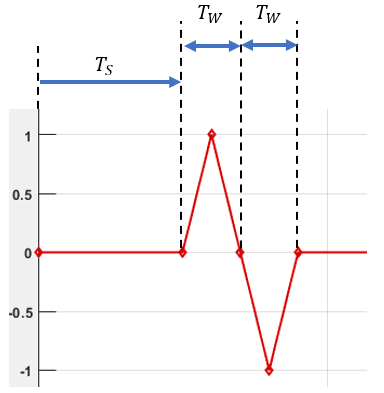

`Bradley Horton : 07-Jan-2018, bradley.horton@mathworks.com.au`

**Scenario #1:      Car velocity is  V = 1 m/sec**

Let's explore what impact the value $T_W$ has:

Evaluating callback 'PostLoadFcn' for simulink_extras
Callback: setsysloc simulink_extras;
root=bdroot;
lock=get_param(root,'Lock');
set_param(root,'Lock','off');
set_param(root,'EnableLBRepository','on');
set_param(root,'Lock',lock);
clear lock;
clear root;
Evaluating callback 'PostLoadFcn' for simulink
Callback: setsysloc_simulink(bdroot)
Evaluating callback 'PostLoadFcn' for simulink_extras
Callback: setsysloc simulink_extras;
root=bdroot;
lock=get_param(root,'Lock');
set_param(root,'Lock','off');
set_param(root,'EnableLBRepository','on');
set_param(root,'Lock',lock);
clear lock;
clear root;
Evaluating callback 'ModelCloseFcn' for simulink/Continuous/PID Controller
Callback: pidpack.PIDConfig.closeTuner(gcbh)
Evaluating callback 'DeleteFcn' for simulink/Continuous/PID Controller
Callback: pidpack.PIDConfig.closeTuner(gcbh)

 ... finished run 1 of 5
 ... finished run 2 of 5
 ... finished run 3 of 5
 ... finished run 4 of 5
 ... finished run 5 of 5

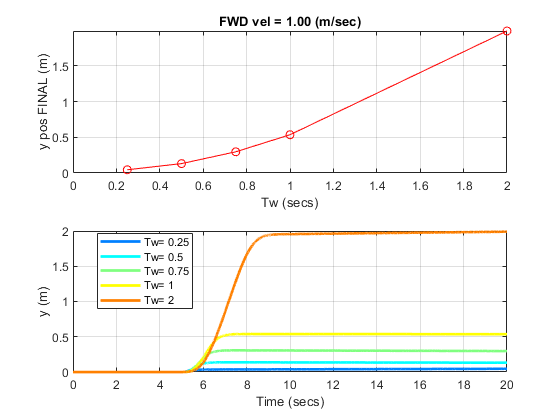

results_table = 5×2 table
    Tw_secs    Y_FINAL_m
    _______    _________

     0.25      0.045037 
      0.5       0.13181 
     0.75       0.29718 
        1       0.53618 
        2        1.9902 


Tw_list     = [ 0.25, 0.5, 0.75, 1, 2]; % (secs)
Peak_deg    = 25; % (degs)
vel_mpersec = 1;  % (m/sec)

results_table = bh_standalone_multisim(Tw_list, Peak_deg, vel_mpersec)

**Scenario #2:       Car velocity is  V = 0.5 m/sec**

Let's explore what impact the value $T_W$ has:


 ... finished run 1 of 5
 ... finished run 2 of 5
 ... finished run 3 of 5
 ... finished run 4 of 5
 ... finished run 5 of 5

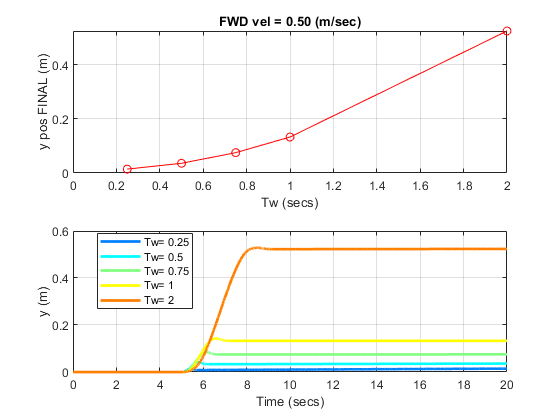

results_table = 5×2 table
    Tw_secs    Y_FINAL_m
    _______    _________

     0.25      0.014386 
      0.5      0.035775 
     0.75      0.075127 
        1       0.13273 
        2       0.52377 


Tw_list     = [ 0.25, 0.5, 0.75, 1, 2]; % (secs)
Peak_deg    = 25; % (degs)
vel_mpersec = 0.5; % (m/sec)

results_table = bh_standalone_multisim(Tw_list, Peak_deg, vel_mpersec)

**Scenario #3:       Car velocity is  V = 0.25 m/sec**

% Tw_list     = [ 2,4,6,8,10]; % (secs)
% Peak_deg    = 25;   % (degs)
% vel_mpersec = 0.25; % (m/sec)
% 
% results_table = bh_standalone_multisim(Tw_list, Peak_deg, vel_mpersec)

# **Local functions go here:**

function a_table = bh_standalone_multisim(Tw_list, Peak_deg, vel_mpersec)

y_pos_end_list = zeros(size(Tw_list) );

for kk = 1:length(Tw_list)
    Tw = Tw_list(kk);
    [y_pos_end_list(kk), Y{kk}, T{kk}] = LOC_run_sim(Tw, Peak_deg, vel_mpersec);
    fprintf('\n ... finished run %d of %d', kk, length(Tw_list) );
end

figure;
 subplot(2,1,1);
   plot(Tw_list, y_pos_end_list, '-ro');
     axis tight, grid on
     xlabel('Tw (secs)');
     ylabel('y pos FINAL (m)');
     ylim([0, max(y_pos_end_list)]);
     xlim([0, max(Tw_list)]);
   
     tmp_str = sprintf('FWD vel = %.2f (m/sec)', vel_mpersec );
     title(tmp_str)
     
  subplot(2,1,2);
    my_cols = jet(length(Tw_list));   
    for kk=1:length(Tw_list)
        plot( T{kk}, Y{kk}, '-', 'Color',  my_cols(kk,:), 'LineWidth', 2 );
        hold on
    end
    
    % add a legend
    tmp_str = string(Tw_list);
    tmp_str = "Tw= " + tmp_str;
    legend(tmp_str, 'Location', 'best');
    grid on
     
    xlabel('Time (secs)');
    ylabel('y (m)');  
    
    % and take care of the OUTPUT table
    Tw_secs   = Tw_list(:);
    Y_FINAL_m = y_pos_end_list(:);
    a_table = table(Tw_secs, Y_FINAL_m);
end

%_#########################################################################
function [y_pos_end, the_y_pos, the_time] = LOC_run_sim(Tw, Peak_deg, vel_mpersec)
   
   % load model parameters into functions workspace
   evalin('base', 'bh_3dof_4wheel_car_sim_params')
   
   % configure simulation
   MODEL_NAME = 'bh_explore_evassive_manoeuvre_automate'; 
   my_simIn  = Simulink.SimulationInput(MODEL_NAME);
   my_simIn  = my_simIn.setModelParameter('StopTime', '20');
   my_simIn  = my_simIn.setModelParameter('SaveOutput', 'on');
   my_simIn  = my_simIn.setModelParameter('OutputSaveName', 'youtNew');
   my_simIn  = my_simIn.setModelParameter('SaveFormat', 'StructureWithTime');
   
   % specify the WORKSPACE variables of interest
   my_simIn = my_simIn.setVariable('Tw',Tw);
   my_simIn = my_simIn.setVariable('Peak_deg',Peak_deg);
   my_simIn = my_simIn.setVariable('vel_mpersec',vel_mpersec);
   
   % run the sim
   simOut = sim(my_simIn);
   
   the_yout_OBJ = simOut.get('youtNew');
   the_yout     = the_yout_OBJ.signals.values;
   the_yout     = squeeze( the_yout );
   
   % get the:
   %  a.) last data point
   %  b.) the y output time data
   %  c.) the time array
   y_pos_end  = the_yout(end);
   the_y_pos  = the_yout(:);
   the_time   =  the_yout_OBJ.time(:);
end
